clear all
load('PIV_LiuHong\P3O190\P3O190_3rd.mat');
load('PTV_LiuHong\P3O190_3rd.mat');

[a,b,c] = size(u);

t = 1

t = 2

t = 3

t = 4

t = 5

t = 6

t = 7

t = 8

t = 9

t = 10

t = 11

t = 12

t = 13

t = 14

t = 15

t = 16

t = 17

t = 18

t = 19

t = 20

t = 21

t = 22

t = 23

t = 24

t = 25

t = 26

t = 27

t = 28

t = 29

t = 30

t = 31

t = 32

t = 33

t = 34

t = 35

t = 36

t = 37

t = 38

t = 39

t = 40

t = 41

t = 42

t = 43

t = 44

t = 45

t = 46

t = 47

t = 48

t = 49

t = 50

t = 51

t = 52

t = 53

t = 54

t = 55

t = 56

t = 57

t = 58

t = 59

t = 60

t = 61

t = 62

t = 63

t = 64

t = 65

t = 66

t = 67

t = 68

t = 69

t = 70

t = 71

t = 72

t = 73

t = 74

t = 75

t = 76

t = 77

t = 78

t = 79

t = 80

t = 81

t = 82

t = 83

t = 84

t = 85

t = 86

t = 87

t = 88

t = 89

t = 90

t = 91

t = 92

t = 93

t = 94

t = 95

t = 96

t = 97

t = 98

t = 99

t = 100

t = 101

t = 102

t = 103

t = 104

t = 105

t = 106

t = 107

t = 108

t = 109

t = 110

t = 111

t = 112

t = 113

t = 114

t = 115

t = 116

t = 117

t = 118

t = 119

t = 120

t = 121

t = 122

t = 123

t = 124

t = 125

t = 126

t = 127

t = 128

t = 129

t = 130

t = 131

t = 132

t = 133

t = 134

t = 135

t = 136

t = 137

t = 138

t = 139

t = 140

t = 141

t = 142

t = 143

t = 144

t = 145

t = 146

t = 147

t = 148

t = 149

t = 150

t = 151

t = 152

t = 153

t = 154

t = 155

t = 156

t = 157

t = 158

t = 159

t = 160

t = 161

t = 162

t = 163

t = 164

t = 165

t = 166

t = 167

t = 168

t = 169

t = 170

t = 171

t = 172

t = 173

t = 174

t = 175

t = 176

t = 177

t = 178

t = 179

t = 180

t = 181

t = 182

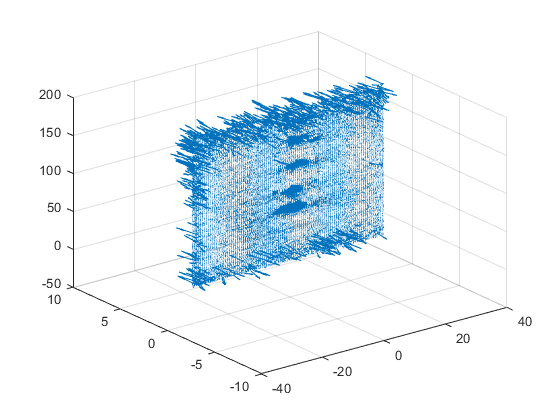

Index in position 1 exceeds array bounds (must not exceed 182).

for t = 1:c
    RealU = rot90(v(:,:,t)); RealV = rot90(-u(:,:,t));
    RealX = rot90(y); RealY = rot90(x); 
    Xscale = RealX(1,:); Yscale = RealY(:,1);
    Zscale = -10:0.5:10; [X,Y,Z] = meshgrid(Xscale,Yscale,Zscale);
    W = zeros(size(X)); U = W; V = W;
    U(:,:,21) = RealU; V(:,:,21) = RealV;
    X = permute(X,[3 1 2]);Y = permute(Y,[3 1 2]);Z = permute(Z,[3 1 2]);
    U = permute(U,[3 1 2]);V = permute(V,[3 1 2]);W = permute(W,[3 1 2]);
    figure(1)
    clf;
    quiver3(X,Z,Y,U,V,W,6);
    hold on
    plot3(traj3D(1:t,1),traj3D(1:t,3),traj3D(1:t,2),'Color','r','LineWidth',2)
    hold off
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    title(['t = ', num2str(t/200 * 1000), ' ms'])
    axis equal
    xlim([-30 30]) 
    ylim([-30 30])
    zlim([0 200])
    F(t) = getframe(gcf);
    t
end

writerObj = VideoWriter('P3O190_3rd.avi');
writerObj.FrameRate = 10;
open(writerObj);
% write the frames to the video
for i=1:length(F)
    % convert the image to a frame
    frame = F(i) ;    
    writeVideo(writerObj, frame);
end
% close the writer object
close(writerObj);